i = 1

rotation = -5

toneValue = 1.0400

eyeSize =      2     2


result = 1

dist = 53.0218

ans = 'Pass'

ans = '========='

i = 2

rotation = 3

toneValue = 0.8900

eyeSize =      2     2


result = 2

dist = 85.5884

ans = 'Pass'

ans = '========='

i = 3

rotation = 0

toneValue = 0.8300

eyeSize =      2     2


result = 3

dist = 44.1540

ans = 'Pass'

ans = '========='

i = 4

rotation = 5

toneValue = 0.9900

eyeSize =      2     2


result = 4

dist = 58.4112

ans = 'Pass'

ans = '========='

i = 5

rotation = 0

toneValue = 0.8300

eyeSize =      2     2


result = 5

dist = 2.8936

ans = 'Pass'

ans = '========='

i = 6

rotation = -4

toneValue = 0.7300

eyeSize =      2     2


result = 6

dist = 513.0526

ans = 'Pass'

ans = '========='

i = 7

rotation = 4

toneValue = 1.1700

eyeSize =      2     2


result = 7

dist = 502.3253

ans = 'Pass'

ans = '========='

i = 8

rotation = -3

toneValue = 1.2400

eyeSize =      2     2


result = 0

dist = 1.0979e+03

ans = 'Fail'

ans = '========='

i = 9

rotation = 2

toneValue = 1.1000

eyeSize =      2     2


result = 9

dist = 180.8556

ans = 'Pass'

ans = '========='

i = 10

rotation = 5

toneValue = 0.7200

eyeSize =      2     2


result = 10

dist = 39.3802

ans = 'Pass'

ans = '========='

i = 11

rotation = -1

toneValue = 0.9900

eyeSize =      2     2


result = 0

dist = 2.9114e+03

ans = 'Fail'

ans = '========='

i = 12

rotation = 1

toneValue = 0.7500

eyeSize =      2     2


result = 12

dist = 536.4965

ans = 'Pass'

ans = '========='

i = 13

rotation = 2

toneValue = 0.7300

eyeSize =      2     2


result = 13

dist = 27.6820

ans = 'Pass'

ans = '========='

i = 14

rotation = 1

toneValue = 1.1300

eyeSize =      2     2


result = 10

dist = 958.9281

ans = 'Fail'

ans = '========='

i = 15

rotation = 0

toneValue = 1.0700

eyeSize =      2     2


result = 15

dist = 204.9312

ans = 'Pass'

ans = '========='

i = 16

rotation = -3

toneValue = 1.0900

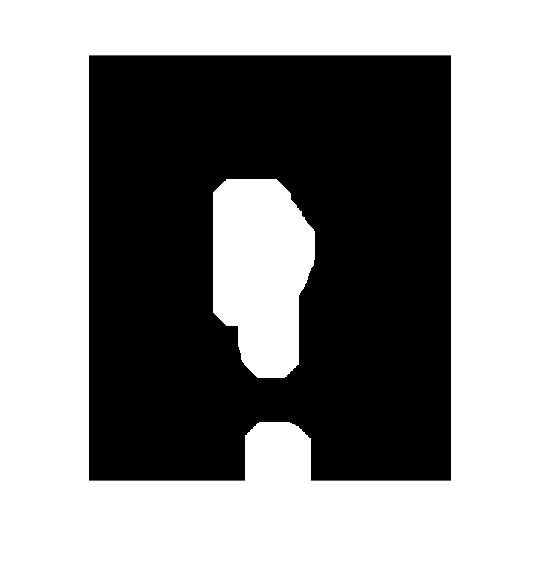

eyeSize =      2     2


result = 16

dist = 346.0877

ans = 'Pass'

ans = '========='

% clear all
% clc
% img = imread(['..\DB1/db1_16.jpg']);
% %6 11
% eyeCoords = findEyeCoordinates(img);
% eyeL = eyeCoords(1, :)
% eyeR = eyeCoords(2, :)
% imgD = im2double(img);
% normalface = normalizeFace(eyeL, eyeR, imgD);
% imshow(img)
% 
% hold on
% plot(eyeCoords(1,1),eyeCoords(1,2), 'r+', 'MarkerSize', 10, 'LineWidth', 1);
% plot(eyeCoords(2,1),eyeCoords(2,2), 'r+', 'MarkerSize', 10, 'LineWidth', 1);
% hold off

% temp = 'C:\Users\jakob\Documents\GitHub\DB0\db0_4.jpg'
% r = 5
% 
% img = imread(temp);
% 
% %img = imrotate(img,r,'bicubic');
% 
% %eyeCoords = findEyeCoordinates(img);
% %cc = colorCorrection(img);
% 
% % img = im2double(img)
% % img = colorCorrection(img);
% % fm = generateFaceMask(img);
% % imshow(img)
% %imshowpair(img, cc, 'montage')
% 
% result=createEigenDB('..\DB1/', img)
totCorrect = 0;
temp = '';
avg = 0;
for i = 1:16
    if i < 10
        temp = strcat('..\DB1/db1_0',int2str(i));
        temp = strcat(temp,'.jpg');
    else
        temp = strcat('..\DB1/db1_',int2str(i));
        temp = strcat(temp,'.jpg');
    end
    i
    
    rotation = randi([-5,5])
    toneValue = randi([70,130])/100
    
    img = imread(temp);
    
    img = imrotate(img,rotation,'bicubic');
    img = img*toneValue;
    
    [result,dist]=createEigenDB('..\DB1/', img);
    result
    dist
    if i == result
        totCorrect = totCorrect +1;
        'Pass'
    else
        'Fail'
    end
    '========='
end

i = 1

eyeSize =      2     2


dist = 1.0701e+03

ans = 'Pass'

ans = '========='

i = 2

eyeSize =      2     2


dist = 938.8525

ans = 'Fail'

ans = '========='

i = 3

eyeSize =      2     2


dist = 659.6397

ans = 'Fail'

ans = '========='

i = 4

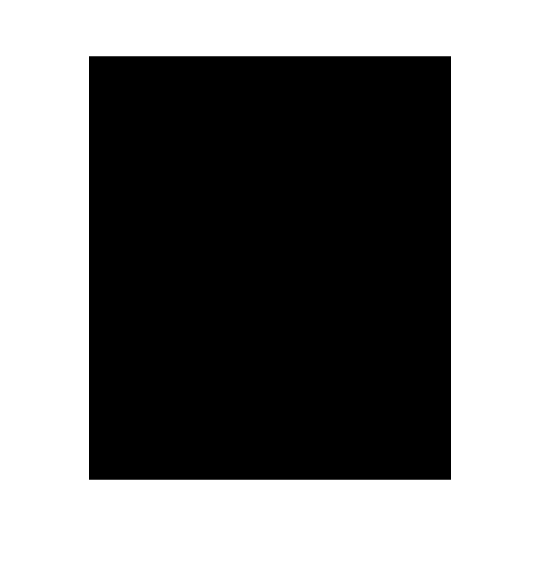

eyeSize =      0     0


Index in position 1 exceeds array bounds.

Error in createEigenDB (line 41)
    normalizedFace = normalizeFace(eyeCoords(1,:),eyeCoords(2,:), imgCC);


for i = 1:4
    temp = strcat('..\DB0/db0_',int2str(i));
    temp = strcat(temp,'.jpg');

    i
    img = imread(temp);
    [result,dist] = createEigenDB('..\DB1/', img);
    dist
    if 0 == result
        totCorrect = totCorrect +1;
        'Pass'
    else
        'Fail'
    end
    '========='
end

'Stats'
totCorrect
procentCorrect = 100*totCorrect/20
avg/20